**E1**

addpath Function\
addpath Data\
addpath Trash\
addpath Legacy\
 
disp("=========================")

disp("Load the data")

Load the data


disp("=========================")


x1 =load('epoch2011.txt');
x2 =load('epoch2012.txt');

% DOF
f1 = length(x1)-1;
f2 =length(x2)-1;
% Residual
v1 = x1-mean(x1);
v2 = x2-mean(x2);
% STD
s1 = std(v1);
s2 = std(v2);
xbar1= mean(x1);
xbar2=mean(x2);
% T1,T2,Chi,FA
flag="Chi"; 
aerfa=5

aerfa =      5


[xbar1,miu1,s1,sig1,f1]=deal(8.73,0,sqrt(0.35),0,14);
[xbar2,miu2,s2,sig2,f2]=deal(8.68,0,sqrt(0.40),0,16);

threshold=1-0.01*aerfa/2

threshold =                      0.975


if flag=="F" 
    Statistic = s1^2/s2^2;
    Con_ab=finv([1-threshold,threshold],f1,f2);
    Con_AB = s1/s2*sqrt(1./[Con_ab(2),Con_ab(1)]);
    
elseif flag=="Chi" 
    Statistic=(f1*s1^2)/sig1^2;
    Con_ab=chi2inv([1-threshold,threshold],f1);
    Con_AB=s1*sqrt(Con_ab/f1);
    
elseif flag=="T1" 
    Statistic = (xbar1-miu1)/s1; 
    Con_ab=tinv([1-threshold,threshold],f1);
    Con_AB=  miu1+s1*Con_ab;
    
elseif flag=="T2" 
    Statistic = (xbar1-xbar2)/sqrt((f1*s1^2+f2*s2^2)/(f1+f2))*sqrt(1/(f1+1)+1/(f2+1));
    Con_ab=tinv([1-threshold,threshold],f1);
    Con_AB=  miu1+s1*Con_ab;
end
disp(sprintf("The interval is [%.3f,%.3f] for %.3f",Con_AB(1),Con_AB(2),threshold))

The interval is [0.375,0.808] for 0.975



if Statistic<=Con_ab(1)  % x_bar1<=Con_AB
    disp('reject the H0, significant smaller then')
elseif Statistic>=Con_ab(2)
    disp('Rejects the H0, significant bigger then')
else
    disp('Fails to reject the H0') 
end

Rejects the H0, significant bigger then


 Different Distribution

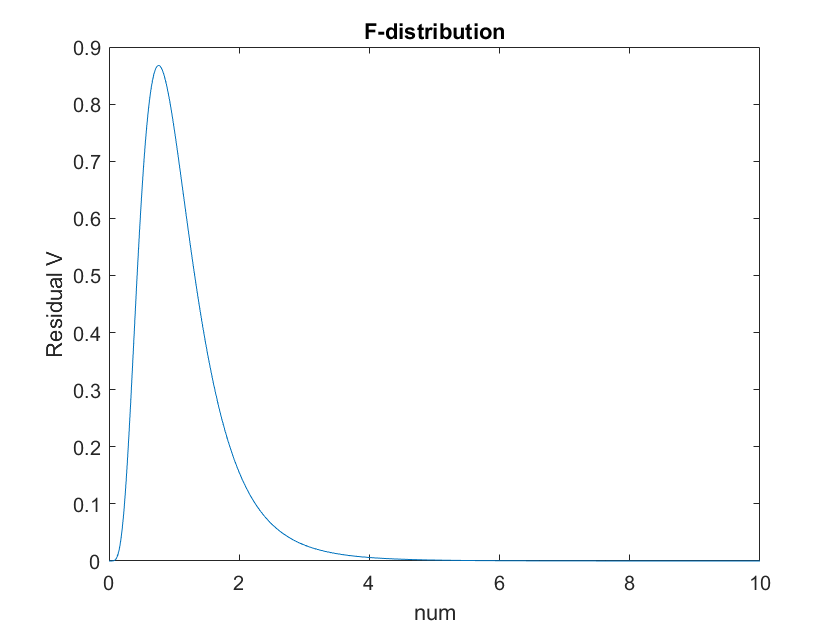

% Plot the F-distribution  pkg load statistics
x_axes = 0:0.01:10;

figure
plot(x_axes,fpdf(x_axes,f1,f2))
title("F-distribution")
xlabel("num")
ylabel("Residual V")

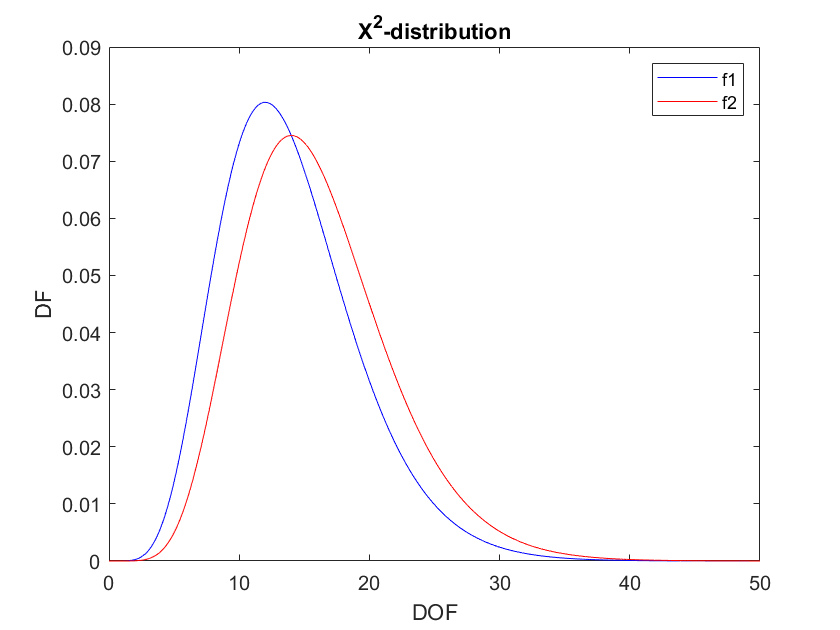


% Plot the x^2 - distribution 
x_axe  = 0:0.01:50;

figure
plot(x_axe ,chi2pdf(x_axe ,f1),'b',x_axe,chi2pdf(x_axe,f2),'r')
title("X^2-distribution")
xlabel("DOF")
ylabel("DF")
legend('f1','f2')

aa

conf=confidence_tool();

[sig1,sig2]=deal(1,1);
[mean1,s1,f1]=conf.mean_s_dof(x1);
[mean2,s2,f2]=conf.mean_s_dof(x1);

[a,b]=conf.get_interval_t(a2prob(5),mean1,s1,f1);

The interval is [33.996,34.003] for 0.975


[a,b]=conf.get_interval_norm(a2prob(5),mean1,s1);

The interval is [33.996,34.003] for 0.975


[a,b]=conf.get_interval_chi(a2prob(5),s1,f1);

The interval is [0.001,0.002] for 0.975


[a,b]=conf.get_interval_f(a2prob(5),s1,s2,f1,f2);

The interval is [0.498,2.006] for 0.975


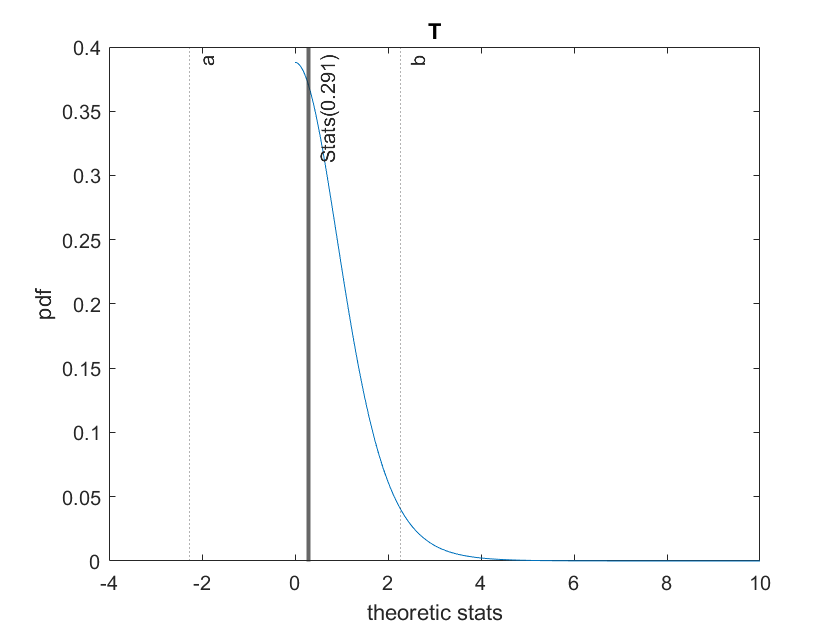

Fails to reject the H0



stats=conf.statistic_test_t(a2prob(5),34,mean1,s1,f1);

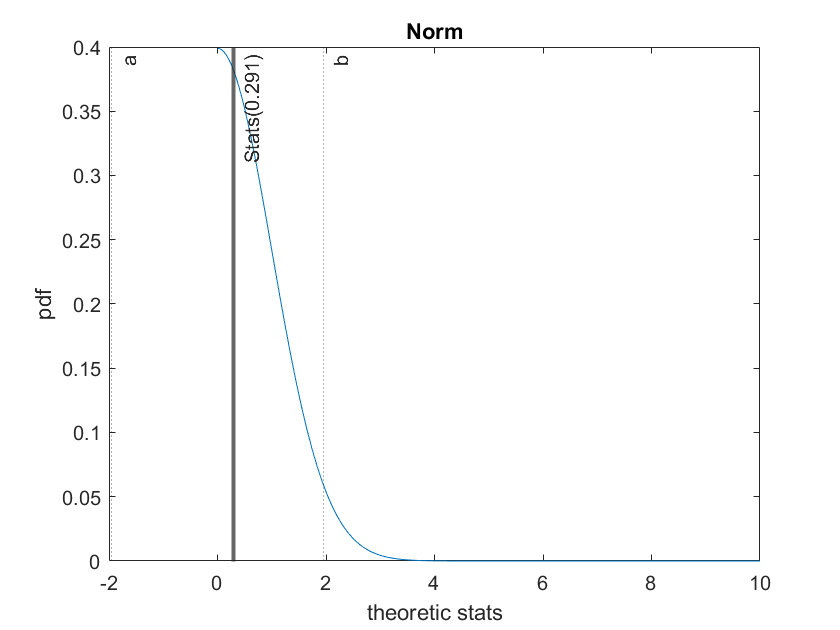

Fails to reject the H0


stats=conf.statistic_test_norm(a2prob(5),34,mean1,s1);

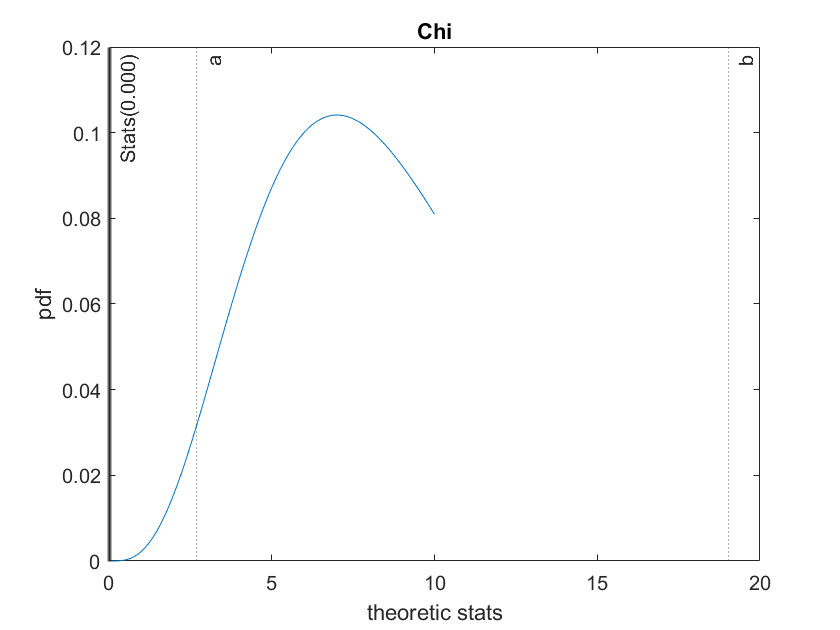

reject the H0, significant smaller then


stats=conf.statistic_test_chi(a2prob(5),1, s1,f1);

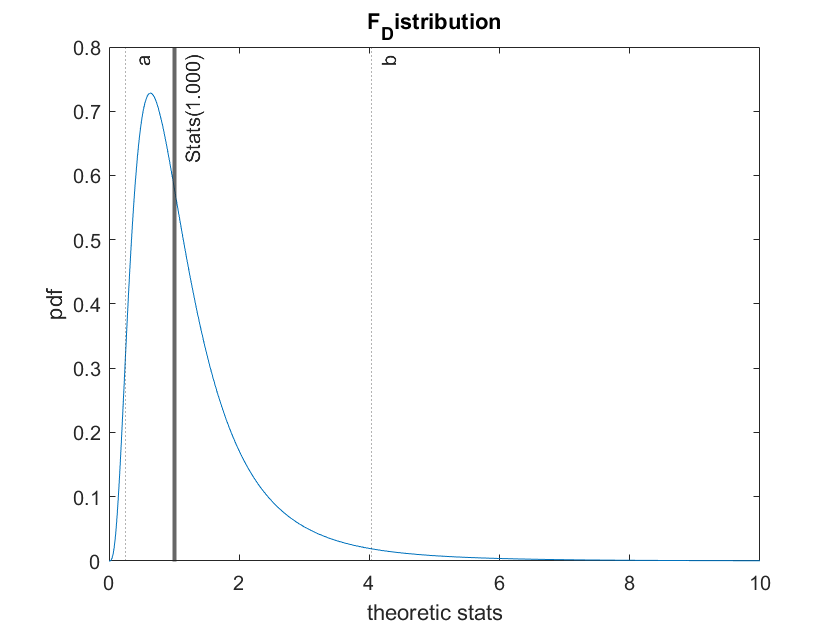

Fails to reject the H0


stats=conf.statistic_test_f(a2prob(5),1,1,s1,s2,f1,f2);